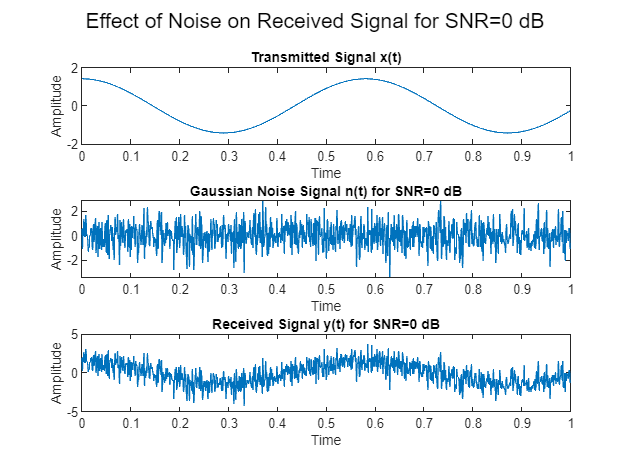

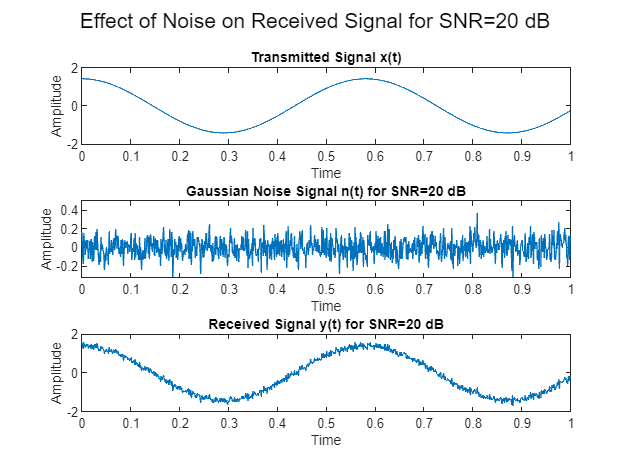

clear all; close all; clc;

%% Generate Transmitted Signal x(t)
Fs = 1000;            % Sampling frequency (Hz)
T = 1;                % Time duration of the signal (s)
t = 0:1/Fs:T-1/Fs;    % Time vector
pi = 3.147;

% Generate Transmitted Signal x(t) (1 kHz sinusoidal signal with unit power)
x_t = sqrt(2) * cos(2*pi*1000*t);

% SNR values in dB
SNR_values = [0, 10, 20];

% Initialize figure index
figure_index = 1;

for SNR_dB = SNR_values
    %% Calculate Noise Power (Variance) from SNR
    SNR_linear = 10^(SNR_dB / 10);  % Convert SNR to linear scale
    noise_variance = var(x_t) / SNR_linear;  % Calculate noise power (variance)

    %% Generate Gaussian Noise Signal n(t)
    gaussian_noise = sqrt(noise_variance) * randn(size(t));  % Gaussian noise with mean 0 and calculated variance

    %% Generate Received Signal y(t)
    y_t = x_t + gaussian_noise;

    %% Plot Received Signal for Different SNR
    figure(figure_index);
    subplot(3, 1, 1);
    plot(t, x_t);
    title('Transmitted Signal x(t)');
    xlabel('Time');
    ylabel('Amplitude');

    subplot(3, 1, 2);
    plot(t, gaussian_noise);
    title(['Gaussian Noise Signal n(t) for SNR=' num2str(SNR_dB) ' dB']);
    xlabel('Time');
    ylabel('Amplitude');

    subplot(3, 1, 3);
    plot(t, y_t);
    title(['Received Signal y(t) for SNR=' num2str(SNR_dB) ' dB']);
    xlabel('Time');
    ylabel('Amplitude');

    sgtitle(['Effect of Noise on Received Signal for SNR=' num2str(SNR_dB) ' dB']);

    figure_index = figure_index + 1;
end